close all; cla; clf;



PlotDisplayNames = {'$\hat{x}_1$', '$\hat{x}_2$', '$\hat{x}_3$', '$\hat{x}_4$', ...
    '$x_1$', '$x_2$', '$x_3$', '$x_4$', ...
    '$e_1$', '$e_2$', '$e_3$', '$e_4$', ...
    '$\hat{x}_1^*$', '$\hat{x}_2^*$', '$\hat{x}_3^*$', '$\hat{x}_4^*$', ... 
    '$x_1^*$', '$x_2^*$', '$x_3^*$', '$x_4^*$', ...
    '$e_1^*$', '$e_2^*$', '$e_3^*$', '$e_4^*$', ...
    };


F = [-28, -56, -10, -13]; % controller gains
K = [8; 12; 20; 29]; % observer gains


Controller Gains, F matrix

F

F =    -28   -56   -10   -13


Observer Gains, K matrix

K

K =      8
    12
    20
    29


### Q7) Open Loop System

A = [0,0,1,0;
    0,0,0,1;
    -2, 1, -1, 1;
    1, -1, 1, -1];

B = [0;0;1;0];
C = [1,0,0,0];
D = 0;


% Now Plot
t_final = 20;                     % time horizon
t = linspace(0, t_final, 10000); % time vector
u = sin(t);                      % input vector

x0      = [10;10;10;10];                 % Initial Condition for the Main System
x0_hat = [0;0;0;0];                 % Initial Condition for the Estimate System

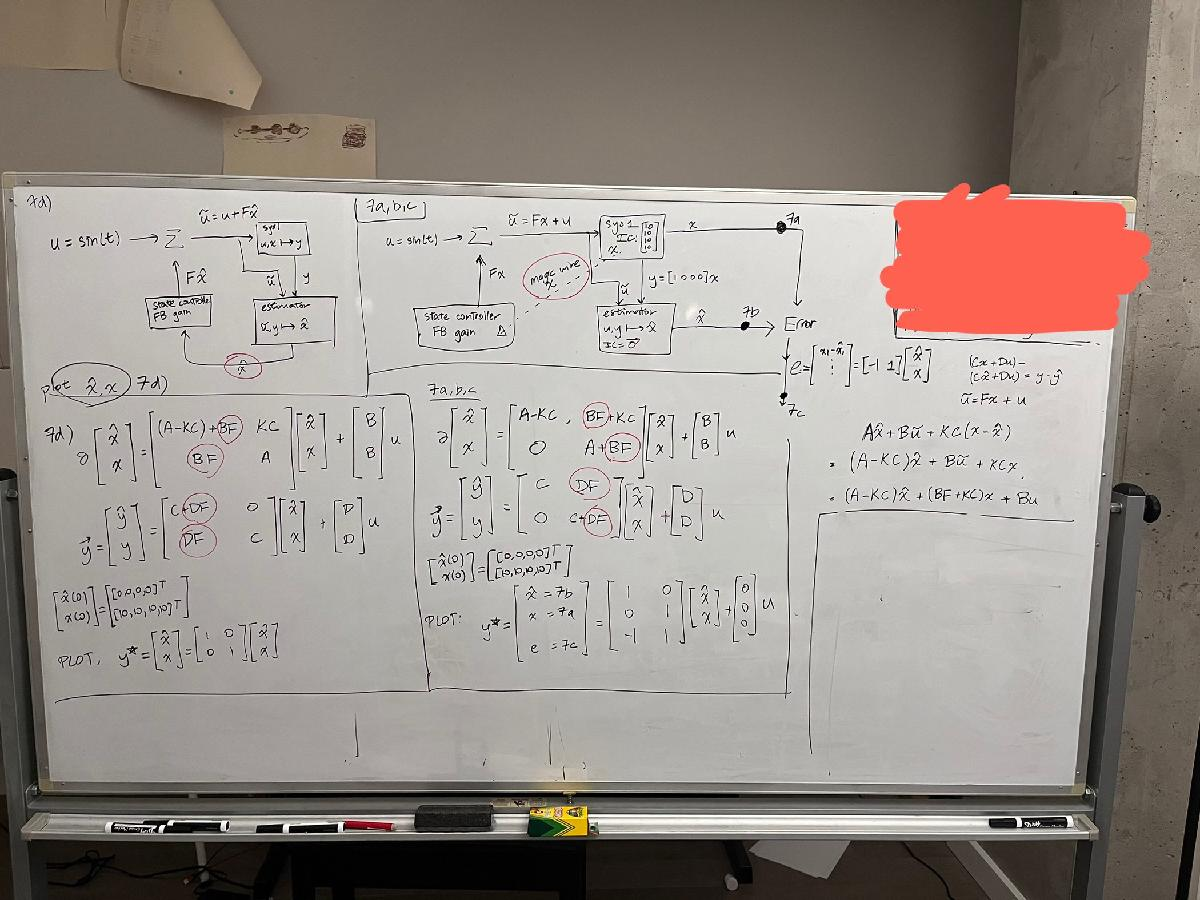

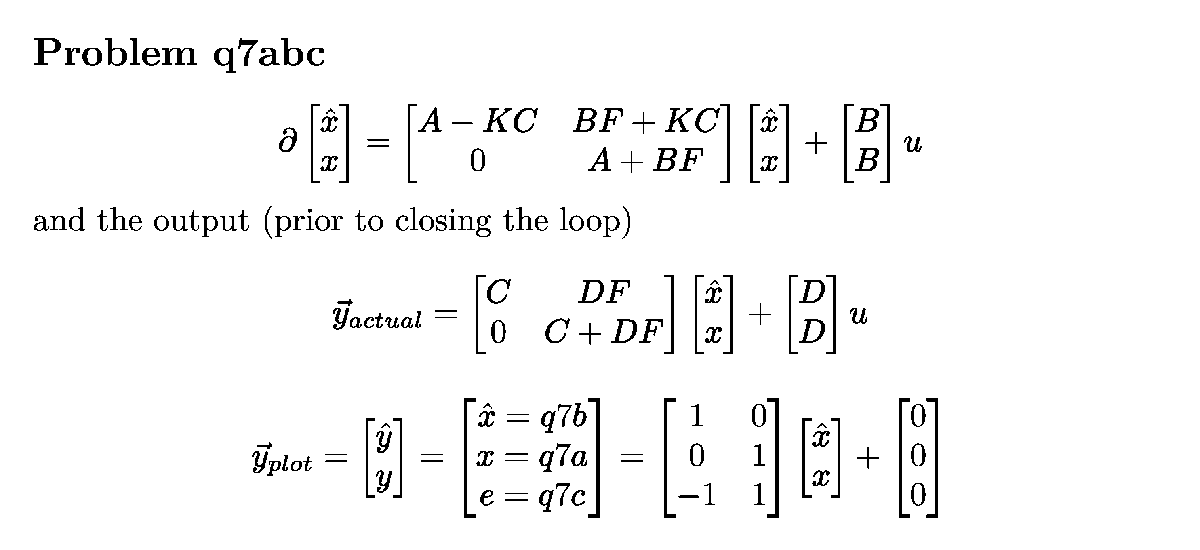

% Construct the Large A Matrix:
A_q7abc = [A-K*C, B*F + K*C; 
           zeros(size(A)), A+B*F];
B_q7abc = [B;B];
C_q7abc = [eye(8);
           -1,0,0,0,1,0,0,0;
           0,-1,0,0,0,1,0,0;
           0,0,-1,0,0,0,1,0;
           0,0,0,-1,0,0,0,1];
D_q7abc = zeros(12,1);
x_q7abc_ic = [x0_hat;x0]; % Initial Condition
sys_q7abc = ss(A_q7abc, B_q7abc, C_q7abc, D_q7abc,'StateName',{'x1_hat','x2_hat','x3_hat','x4_hat','x1','x2','x3','x4'},'InputName','u','OutputName',{'x1_hat','x2_hat','x3_hat','x4_hat','x1','x2','x3','x4','e1','e2','e3','e4'});

% Generate lsim output
[y_q7abc, tOut, x_q7abc] = lsim(sys_q7abc, u, t, x_q7abc_ic);



### Problem 7ab) Trajectory Comparison plots, xhat and x for all four elements

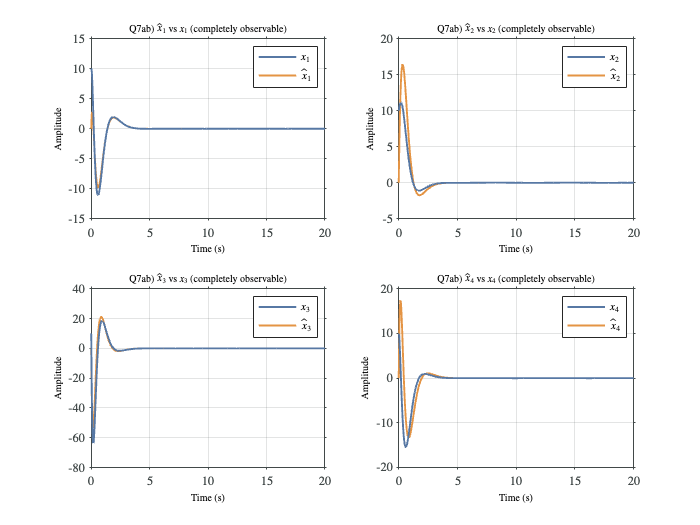

figure;
for i = 1:4
    subplot(2,2,i);
    plot(t, y_q7abc(:,i), 'DisplayName', PlotDisplayNames{i});
    hold on;
    plot(t, y_q7abc(:,i+4), 'DisplayName', PlotDisplayNames{i+4});
    % Style
    title(['Q7ab) $\hat{x}_', num2str(i), '$ vs $x_', num2str(i), '$ (completely observable)'], 'interpreter', 'latex');
    legend('Interpreter', 'latex');
    xlabel('Time (s)');
    ylabel('Amplitude');
    grid on;
    STANDARDIZE_SCOPE_WITH_SUBPLOTS(gcf);
end
hold off;
print(gcf, ['q7ab_trajectories','.pdf'], '-vector', '-dpdf', '-bestfit');

saveas(gcf,'q7ab_trajectories.png');

### Problem 7c) Error Trajectories

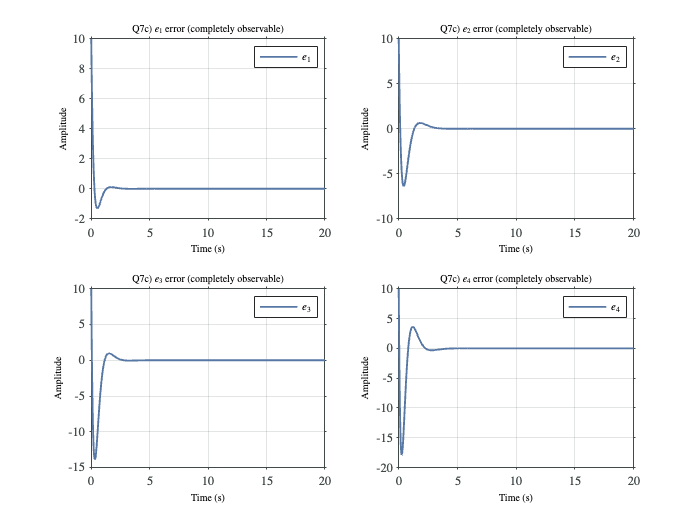

% Plot Individual Error Trajectories

figure;
for i = 1:4    
    subplot(2,2,i);
    plot(t, y_q7abc(:,i+8), 'DisplayName', PlotDisplayNames{i+8});
    title(['Q7c) $e_', num2str(i), '$ error (completely observable)'], 'interpreter', 'latex');
    % Style
    legend('Interpreter', 'latex');
    xlabel('Time (s)');
    ylabel('Amplitude');
    grid on;
    STANDARDIZE_SCOPE_WITH_SUBPLOTS(gcf);
end

print(gcf, ['q7c_errors_','.pdf'], '-vector', '-dpdf', '-bestfit');

saveas(gcf,'q7c_errors.png');

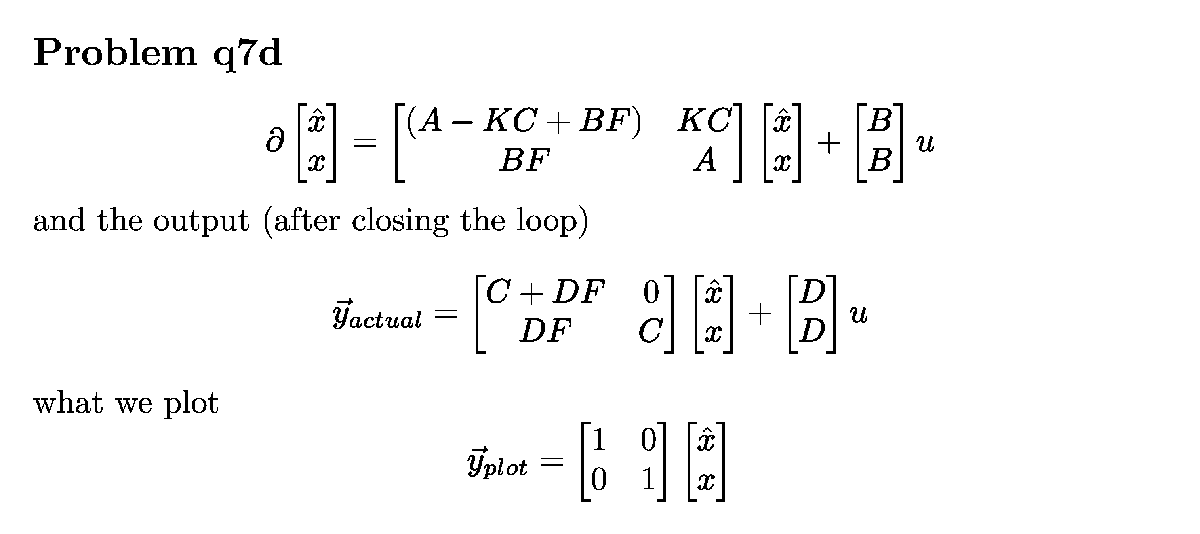

The * on any state/output variables denote the closed loop system.

A_q7d = [A-K*C + B*F, K*C; 
           B*F, A];
B_q7d = [B;B];
C_q7d = eye(8);
D_q7d = zeros(8,1);
x_q7d_ic = [x0_hat;x0]; % Initial Condition as before

sys_q7d = ss(A_q7d, B_q7d, C_q7d, D_q7d);

% Generate lsim output
[y_q7d, tOut, x_q7d] = lsim(sys_q7d, u, t, x_q7d_ic);

### Q7d) Plotting the closed-loop system

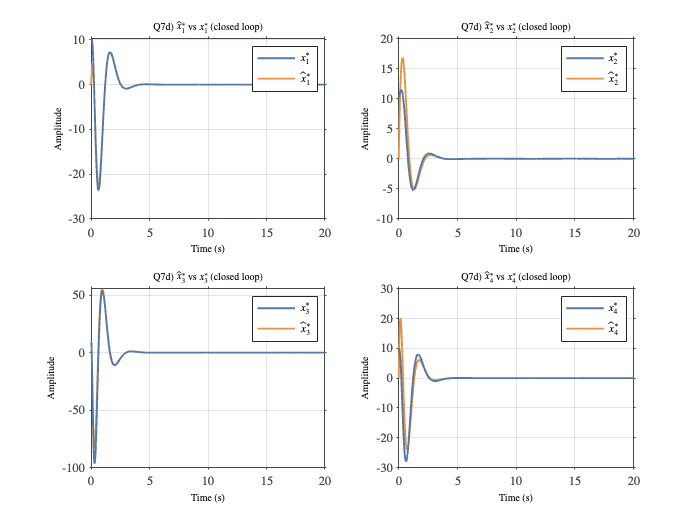

figure;
for i = 1:4
    subplot(2,2,i)
    plot(t, y_q7d(:,i), 'DisplayName', PlotDisplayNames{i+12});
    hold on;
    plot(t, y_q7d(:,i+4), 'DisplayName', PlotDisplayNames{i+4+12});
    % Style
    title(['Q7d) $\hat{x}^*_', num2str(i), '$ vs $x^*_', num2str(i), '$ (closed loop)'], 'interpreter', 'latex');
    legend('Interpreter', 'latex');
    xlabel('Time (s)');
    ylabel('Amplitude');
    grid on;
    STANDARDIZE_SCOPE_WITH_SUBPLOTS(gcf);
end
hold off;
    
print(gcf, ['q7d_systems','.pdf'], '-vector', '-dpdf', '-bestfit');

saveas(gcf,'q7d_systems.png');

### % Plotting all four together Q7abc + Q7d of Estimated System and Main System

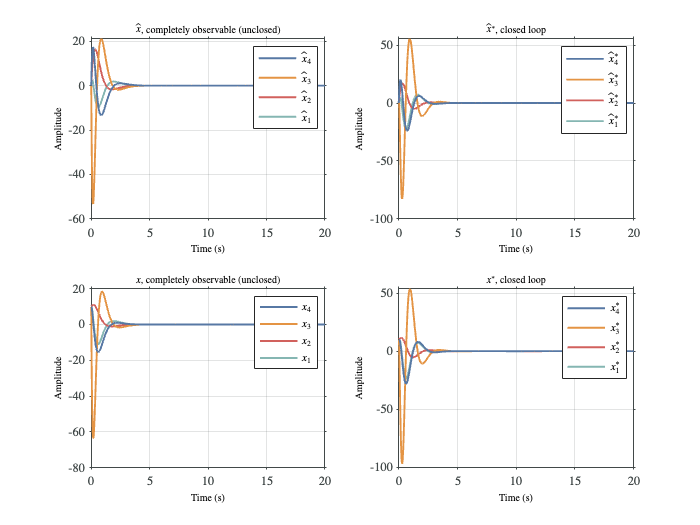

figure;
for i = 1:4
    subplot(2,2,1);
    % x_hat, completely observable (unclosed)
    hold on;
    plot(t, y_q7abc(:,i),'DisplayName', PlotDisplayNames{i});
    
    subplot(2,2,2);
    % x_hat, closed
    hold on;
    plot(t, y_q7d(:,i),'DisplayName',  PlotDisplayNames{i+12})

    subplot(2,2,3);
    % x, completely observable (unclosed)
    hold on;
    plot(t,y_q7abc(:,i+4),'DisplayName', PlotDisplayNames{i+4})

    subplot(2,2,4);
    % x, closed
    hold on;
    plot(t,y_q7d(:,i+4),'DisplayName', PlotDisplayNames{i+4+12})
end

subplot(2,2,1);
title('$\hat{x}$, completely observable (unclosed)', 'interpreter', 'latex');

subplot(2,2,2);
title('$\hat{x}^*$, closed loop', 'interpreter', 'latex');

subplot(2,2,3);
title('$x$, completely observable (unclosed)', 'interpreter', 'latex');

subplot(2,2,4);
title('$x^*$, closed loop', 'interpreter', 'latex');
hold off;
for i = 1:4
    subplot(2,2,i);
    legend('Interpreter', 'latex');
    xlabel('Time (s)');
    ylabel('Amplitude');
    grid on;
end
STANDARDIZE_SCOPE_WITH_SUBPLOTS(gcf);
print(gcf, ['q7d_comparison_with_main_system','.pdf'], '-vector', '-dpdf', '-bestfit');
saveas(gcf,'q7d_comparison_with_main_system.png');